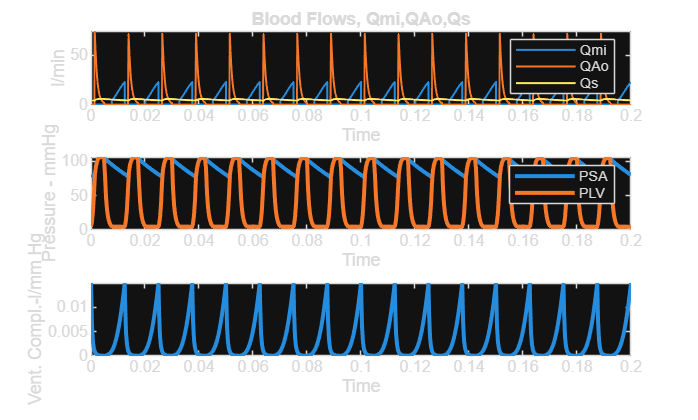

% This Model by Bradley Sutton, PhD, at the University of Illinois,
% modified by Claude Lieber, MD, FGCU
% has been adapted from the MATLAB code presented in Hoppensteadt and Peskin
% "Modeling and Simulation in Medicine and the Life Sciences"
clear
close all
clc
% Time parameters
T = 0.0125;                      % Duration of heartbeat: min
Ts = 0.0050;                     % Duration of systole: min
dt = .00005*T;                   % This choice implies 20,000 timesteps per cardiac cycle
Beats=16*T;                      % 16 heart beats displayed
% Compliance and resistance parameters. Note that valve resistances are not
% supposed to be realistic, just small enough to be negligible
Csa = .00175;  % Systemic arterial compliance: L/mmHg, original=0.0175
Rs = 17.28;    % Systemic resistance: mmHg/(L/min) - initial value 17.28
Rmi =0.01;     % mitral valve resistance: mmHg/(L/min) - initial value 0.01
RAo =0.01;     % Aortic valve resistance: mmHg/(L/min) initial is 0.01
AoBkflo=0.00;  % 1/Resistance to back flow in the aortic valve
               % Normally zero (1/infinity)- no back flow allowed
Vlvd = .027;   % Left ventricular volume when PLV=0 (ESV)
Vsad = .825;   % Systemic arterial volume when Psa=diastol
Pla = 5;       % Left atrial pressure: mmHg Initially 5 mmHg
% Parameters for Clv(t)
CLVD =0.0150;  % Max (diastolic) value of CLV: L/mmHg Initially 0.0146
CLVS = 5e-5;   % Min (systolic) value of CLV: L/mmHg initially 5e-5
tauS = .0025;  % CLV time constant during systole: min (0.0025)
tauD = .005;   % CLV time constant during diastole: min (0.001)
% Initialization parameters
Plvi = 5;      % Initial value of Plv: mmHg
Psai = 80;     % initial value of Psa: mmHg
sim('Cardio_SA_LV')

t=BloodFlows.time;

% Create figure with blood flows
figure('color','white')
subplot(3,1,1)
plot(t,BloodFlows.signals.values,'linewidth',1)
legend('Qmi','QAo','Qs')
title('Blood Flows, Qmi,QAo,Qs')
xlabel('Time')
ylabel('l/min')

subplot(3,1,2)
plot(t,PSA,'linewidth',2);hold on;plot(t,PLV,'linewidth',2);hold off
legend('PSA','PLV')
xlabel('Time')
ylabel('Pressure - mmHg')

subplot(3,1,3)
plot(t,CLV,'linewidth',2)
xlabel('Time')
ylabel('Vent. Compl.-l/mm Hg')

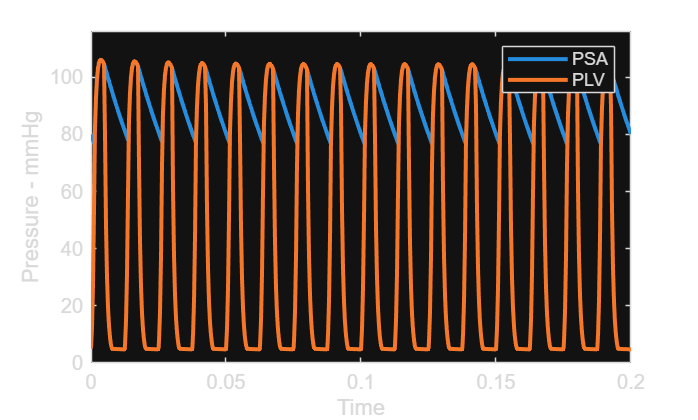


% Additional pressure-volume plots
figure('color','white')
plot(t,PSA,'linewidth',2);hold on;plot(t,PLV,'linewidth',2);hold off
legend('PSA','PLV')
xlabel('Time')
ylabel('Pressure - mmHg')
axis([0 max(t) 0 max(PLV)+10])

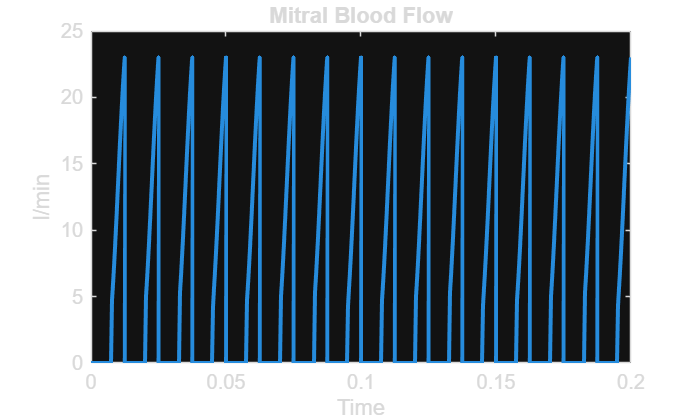


figure('color','white'); plot(t,BloodFlows.signals.values(:,1),'linewidth',2)
title('Mitral Blood Flow')
xlabel('Time')
ylabel('l/min')

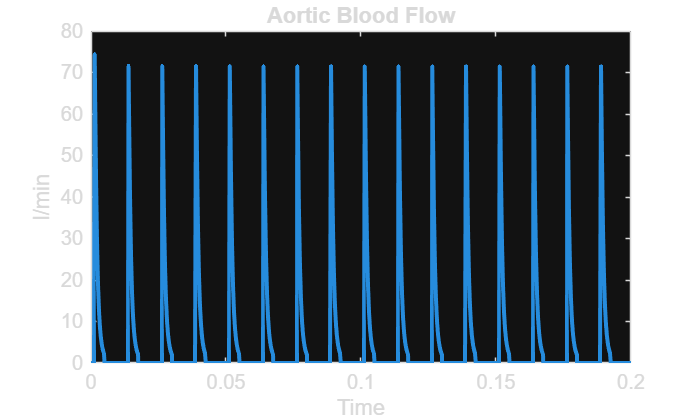


figure('color','white'); plot(t,BloodFlows.signals.values(:,2),'linewidth',2)
title('Aortic Blood Flow')
xlabel('Time')
ylabel('l/min')

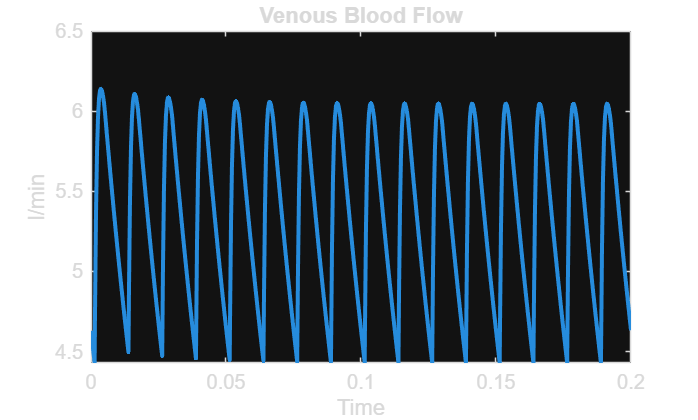


figure('color','white'); plot(t,BloodFlows.signals.values(:,3),'linewidth',2)
title('Venous Blood Flow')
xlabel('Time')
ylabel('l/min')

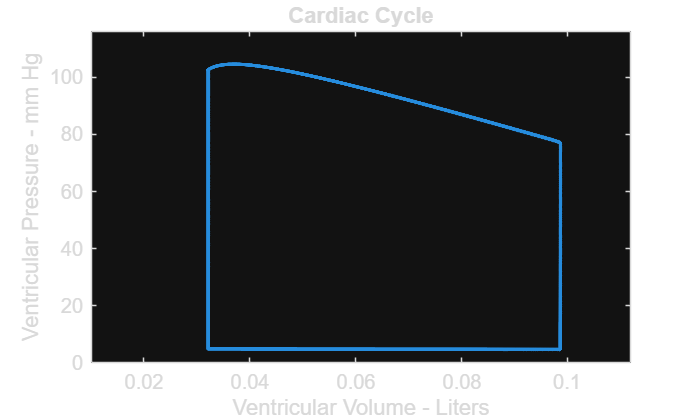


figure('color','white')
plot(VLV(300000:end),PLV(300000:end),'linewidth',2);
title('Cardiac Cycle')
xlabel('Ventricular Volume - Liters')
ylabel('Ventricular Pressure - mm Hg')
axis([0.01 max(VLV)+0.01 0 max(PLV)+10])

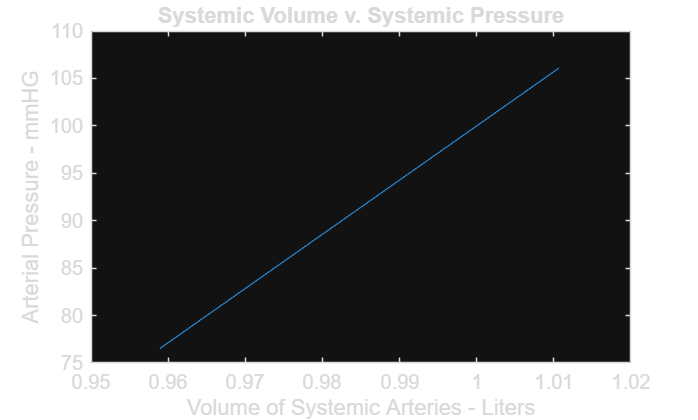


figure('color','white')
plot(VSA,PSA)
title('Systemic Volume v. Systemic Pressure')
xlabel('Volume of Systemic Arteries - Liters')
ylabel('Arterial Pressure - mmHG')


% --- NEW CODE SECTION FOR FLOW CALCULATIONS ---
% Calculate the flow per beat for each flow
flow_per_beat_Qmi = trapz(t, BloodFlows.signals.values(:,1)); % Mitral flow
flow_per_beat_QAo = trapz(t, BloodFlows.signals.values(:,2)); % Aortic flow
flow_per_beat_Qs = trapz(t, BloodFlows.signals.values(:,3));  % Systemic venous flow

% Calculate the flow per minute
HR = 1/T; % Heart rate in beats per minute (since T is in minutes)
flow_per_min_Qmi = flow_per_beat_Qmi * HR; % Mitral flow per minute
flow_per_min_QAo = flow_per_beat_QAo * HR; % Aortic flow per minute
flow_per_min_Qs = flow_per_beat_Qs * HR;  % Systemic venous flow per minute

% Print the results for question iii
fprintf('\n--- FLOW ANALYSIS ---\n');


--- FLOW ANALYSIS ---


fprintf('iii. The ONE aspect that must be the same for pulmonary artery flow, mitral flow, and aortic flow per minute is the MEAN FLOW RATE.\n');

iii. The ONE aspect that must be the same for pulmonary artery flow, mitral flow, and aortic flow per minute is the MEAN FLOW RATE.


fprintf('     In a steady-state cardiovascular system, the volume of blood pumped per minute through each region must be equal.\n');

     In a steady-state cardiovascular system, the volume of blood pumped per minute through each region must be equal.


fprintf('     This is because the cardiovascular system is a closed loop, and the same volume of blood that enters must be pumped out.\n\n');

     This is because the cardiovascular system is a closed loop, and the same volume of blood that enters must be pumped out.




% Print the results for question c
fprintf('c. Flow calculations per minute:\n');

c. Flow calculations per minute:


fprintf('   Flow per minute through Mitral Valve: %.2f liters/min\n', flow_per_min_Qmi);

   Flow per minute through Mitral Valve: 85.24 liters/min


fprintf('   Flow per minute through Aortic Valve: %.2f liters/min\n', flow_per_min_QAo);

   Flow per minute through Aortic Valve: 85.51 liters/min


fprintf('   Flow per minute through Systemic Venous: %.2f liters/min\n', flow_per_min_Qs);

   Flow per minute through Systemic Venous: 85.50 liters/min



% Print additional explanation for question b
fprintf('\nb. To calculate the quantity of flow in one minute through each valve or vascular bed:\n');


b. To calculate the quantity of flow in one minute through each valve or vascular bed:


fprintf('   1. Integrate the flow rate over one cardiac cycle to get the volume per beat using trapz()\n');

   1. Integrate the flow rate over one cardiac cycle to get the volume per beat using trapz()


fprintf('   2. Multiply by the heart rate (beats per minute) to get the volume per minute\n');

   2. Multiply by the heart rate (beats per minute) to get the volume per minute


fprintf('   3. The heart rate is calculated as 1/T where T is the duration of one cardiac cycle in minutes\n');

   3. The heart rate is calculated as 1/T where T is the duration of one cardiac cycle in minutes


% --- END OF FLOW CALCULATIONS SECTION ---

% --- NEW CODE SECTION FOR VOLUME, STROKE VOLUME, CARDIAC OUTPUT, AND WORK CALCULATIONS ---
% Calculate the number of time steps in one cardiac cycle
Cycle = T/dt;
Syst = Ts/dt;
Diastole = Cycle - Syst;

% vi. End Diastolic Volume (EDV) and End Systolic Volume (ESV)
EDV = VLV(end);                  % End Diastolic Volume (maximum volume)
ESV = VLV(end-Diastole+1);       % End Systolic Volume (minimum volume)

fprintf('\n--- VOLUME ANALYSIS ---\n');


--- VOLUME ANALYSIS ---


fprintf('vi. End Diastolic Volume (EDV): %.4f liters\n', EDV);

vi. End Diastolic Volume (EDV): 0.0985 liters


fprintf('    End Systolic Volume (ESV): %.4f liters\n', ESV);

    End Systolic Volume (ESV): 0.0321 liters



% vii. Stroke Volume (SV)
SV = EDV - ESV;                  % Stroke Volume = EDV - ESV
SV_ml = SV * 1000;               % Convert to milliliters

fprintf('vii. Stroke Volume (SV): %.4f liters (or %.1f ml)\n', SV, SV_ml);

vii. Stroke Volume (SV): 0.0664 liters (or 66.4 ml)



% viii. Cardiac Output (CO)
CO = SV * HR;                    % Cardiac Output = Stroke Volume * Heart Rate

fprintf('viii. Cardiac Output (CO): %.2f liters/min\n', CO);

viii. Cardiac Output (CO): 5.31 liters/min


fprintf('      Formula: CO = SV * HR\n');

      Formula: CO = SV * HR


fprintf('      Where:\n');

      Where:


fprintf('        SV = Stroke Volume = %.4f liters\n', SV);

        SV = Stroke Volume = 0.0664 liters


fprintf('        HR = Heart Rate = %.0f beats/min\n', HR);

        HR = Heart Rate = 80 beats/min


fprintf('      Therefore: CO = %.4f * %.0f = %.2f liters/min\n', SV, HR, CO);

      Therefore: CO = 0.0664 * 80 = 5.31 liters/min



% ix. Work done by the ventricle in one cycle
% Calculate the work done during systole using the pressure-volume loop
deltaP = diff(PLV(end-Cycle:end-Cycle+Syst)); % Pressure difference during systole
SumV = (VLV(end-Cycle:end-Cycle+Syst-1) + VLV(end-Cycle+1:end-Cycle+Syst))/2; % Average volume during systole
W = sum(deltaP .* SumV); % Work in mmHg*L
W_joules = W * 0.13332; % Convert work from mmHg*L to joules (1 mmHg*L = 0.13332 J)

fprintf('ix. Work done by the ventricle in one cycle: %.4f joules\n', W_joules);

ix. Work done by the ventricle in one cycle: 1.2047 joules


fprintf('    Calculation:\n');

    Calculation:


fprintf('    1. Calculate pressure differences during systole: deltaP = diff(PLV)\n');

    1. Calculate pressure differences during systole: deltaP = diff(PLV)


fprintf('    2. Calculate average volumes during systole: SumV = (VLV(k) + VLV(k+1))/2\n');

    2. Calculate average volumes during systole: SumV = (VLV(k) + VLV(k+1))/2


fprintf('    3. Calculate work: W = sum(deltaP .* SumV) in mmHg*L\n');

    3. Calculate work: W = sum(deltaP .* SumV) in mmHg*L


fprintf('    4. Convert to joules: W_joules = W * 0.13332 (since 1 mmHg*L = 0.13332 J)\n');

    4. Convert to joules: W_joules = W * 0.13332 (since 1 mmHg*L = 0.13332 J)


fprintf('    Final work: %.4f mmHg*L = %.4f joules\n', W, W_joules);

    Final work: 9.0359 mmHg*L = 1.2047 joules


% --- END OF VOLUME, STROKE VOLUME, CARDIAC OUTPUT, AND WORK CALCULATIONS SECTION ---
